
figure;
hold on;
neuron_type_now = spk_type(1,1,:);
plot(1:160, neuron_type_now(:), 'b-', 'LineWidth', 1.5);
n = size(spk_neuron_type(1,1).lap_position,1)

n = 59

color_map = parula(n);

neuron_trial_now = spk_neuron_type(3,1).lap_position(n,:)

neuron_trial_now =    -0.4482   -0.4482   -0.4482   -0.4482   -0.4482   -0.4482   -0.4482   -0.3717    0.2468   -0.2400   -0.4482   -0.4379   -0.2753   -0.4258   -0.4482   -0.4482   -0.4482   -0.4482   -0.1538   -0.1538    1.6373    1.6373    0.3500   -0.4482   -0.4482   -0.4482   -0.4482    0.7601    1.1810   -0.3532   -0.4482   -0.4482   -0.4482   -0.4482   -0.4482   -0.4482   -0.4482   -0.4482   -0.4482    0.8334    1.3462   -0.4482    0.6059    5.1061    2.4643   -0.3600   -0.4482   -0.4482   -0.4482   -0.4482


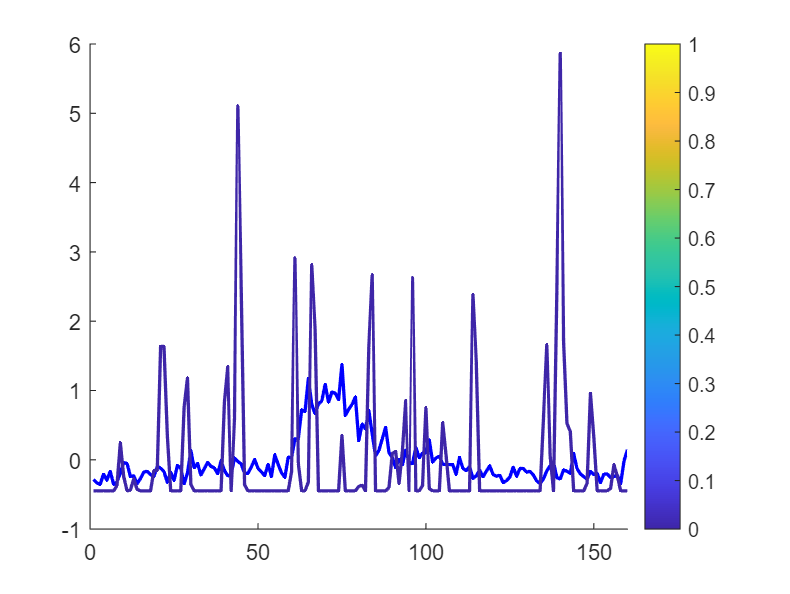

plot(1:160, neuron_trial_now(1, :), 'Color', [color_map(1, :),0.1], 'LineWidth', 1.5);
colorbar;

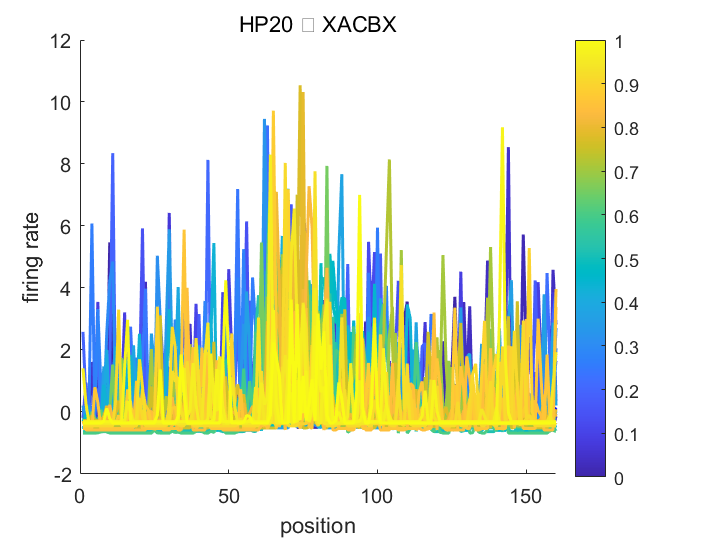

n = 59

错误使用 matlab.graphics.internal.name (第 112 行)
无法创建输出文件 'W:\LWX\Data_Processing\2p\HP20\250606\behavior&imaging\tiral_neuron\HP20__XACBX.png'。

出错 print (第 71 行)
pj = matlab.graphics.internal.name( pj );

出错 saveas (<a

save_folder = fullfile(save_path_str, 'tiral_neuron');
if ~exist(save_folder, 'dir')
    mkdir(save_folder);
end
figure;

hold on;
neuron_type_now = spk_type(1,1,:);
plot(1:160, neuron_type_now(:), 'b-', 'LineWidth', 1.5);
for q =1:use_cell_number
    for p = 1:n_type
        n = size(spk_neuron_type(1,p).lap_position,1)
        color_map = parula(n);

        for i = 1:n
            neuron_trial_now = spk_neuron_type(index_responsive(q),p).lap_position;
        
            plot(1:160, neuron_trial_now(i, :), 'Color', color_map(i, :), 'LineWidth', 1.5);
        end
        
        hold off;
        xlabel('position');
        ylabel('firing rate');
        img_title =sprintf('%s %s %s', number, index_responsive(q), trial_name(p));
        title(img_title);
        colorbar;
        img_file_name = sprintf('%s_%s_%s.png', number, index_responsive(q), trial_name(p));
        img_file_path = fullfile(save_folder, img_file_name);
        saveas(gcf, img_file_path);
        close(gcf);
    end
end